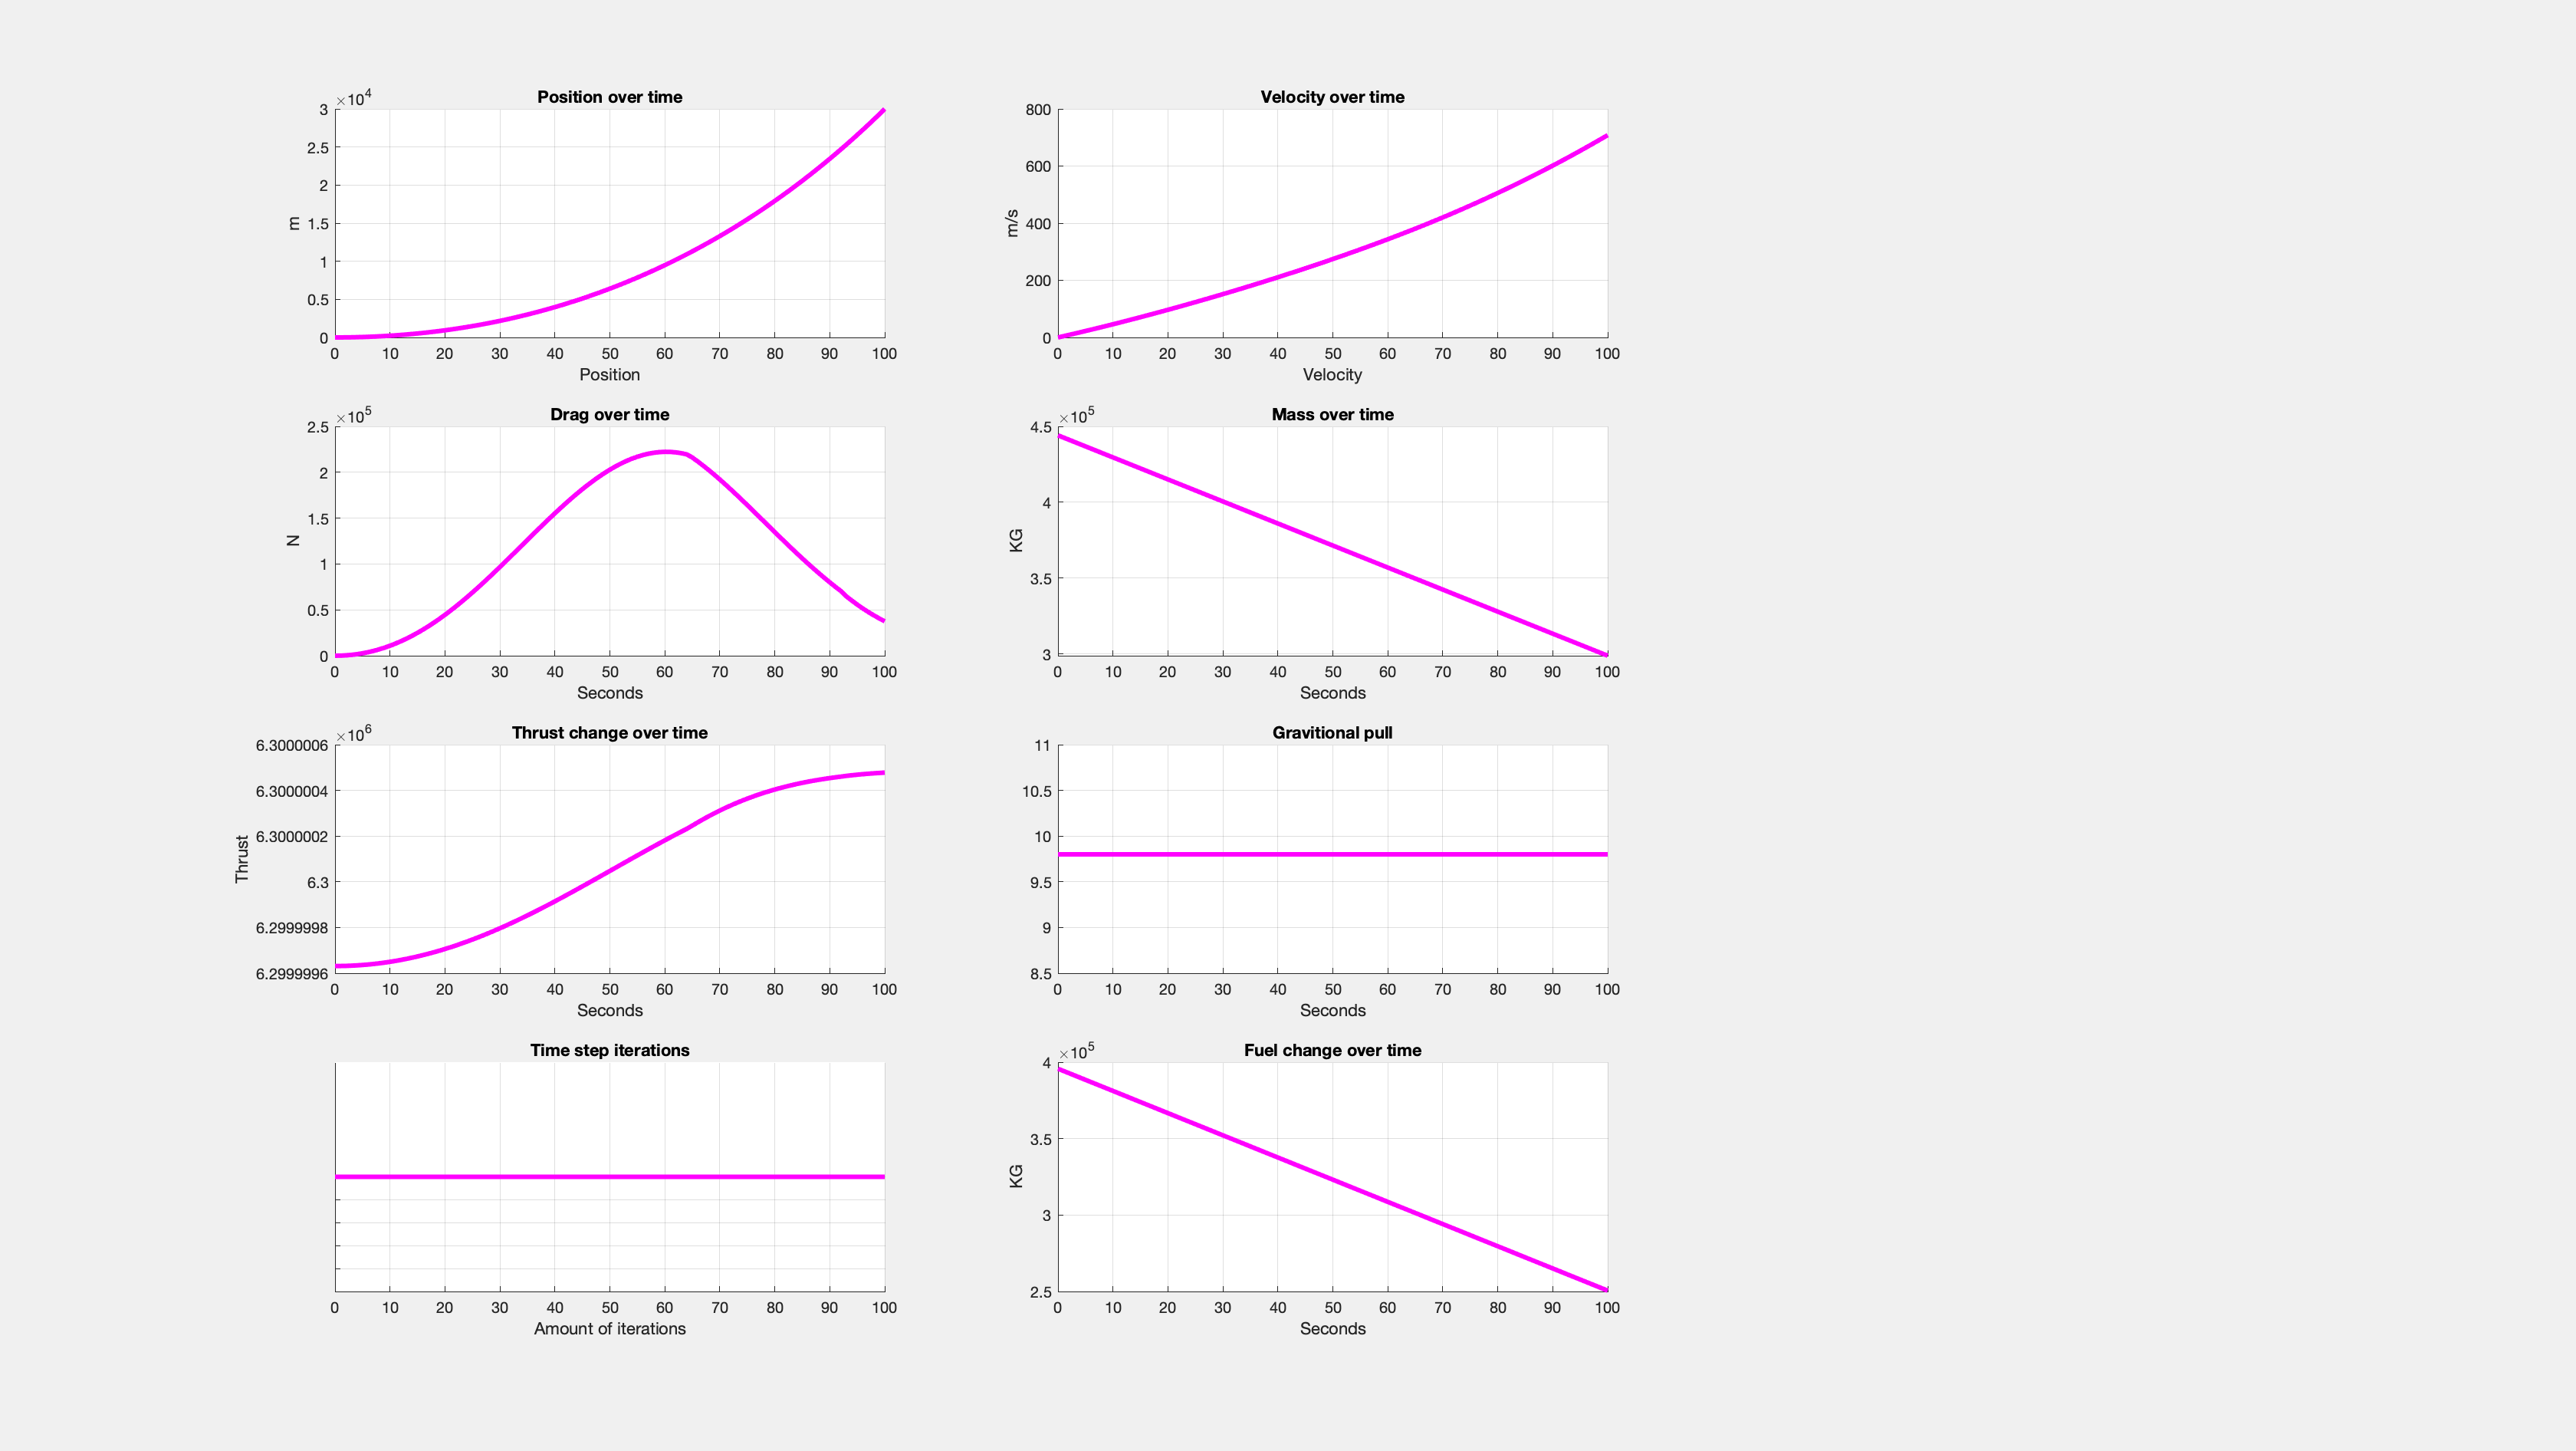

% Define initial conditions
x0 = 0; % Initial x position
y0 = 0; % Initial y position
z0 = 0; % Initial z position
vx0 = 0; % Initial x velocity
vy0 = 0; % Initial y velocity
vz0 = 0; % Initial z velocity

% Define time range for simulation
t0 = 0; % Start time
tf = 100; % End time
dt = 1; % Time step
t = t0:dt:tf; % Time range for simulation

y_0 = [x0, y0, z0, vx0, vy0, vz0]; 
[t, y] = ode45(@rocketDynamics, t, y_0);

plotMD(y,t);

%RK4
tspan = [0 100];
y0 = [0 0 0 0 0 0];
h = 1;
[t2, y2] = rk4(@rocketDynamics, tspan, y0, h);


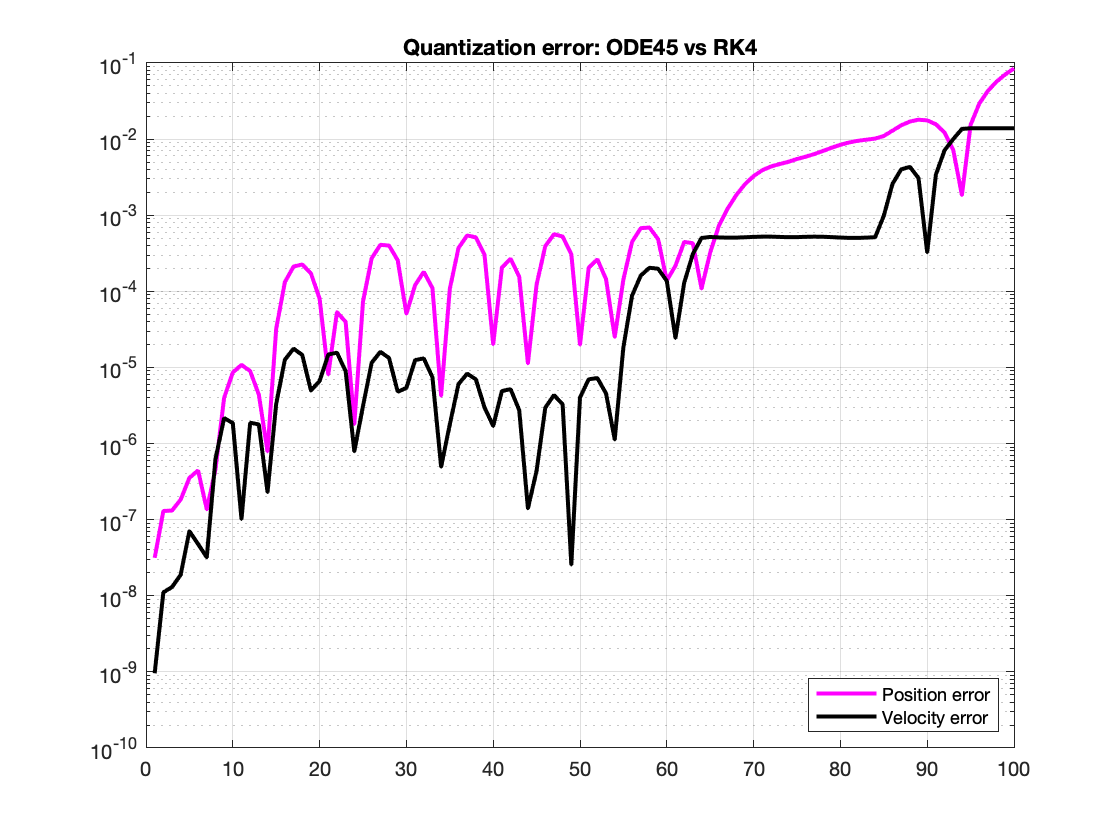

fel1 = abs(y2 - y);

clf

semilogy(t,fel1(:,3),'m','LineWidth',2)
hold on 
semilogy(t,fel1(:,6),'black','LineWidth',2)
title("Quantization error: ODE45 vs RK4")
legend("Position error","Velocity error")
legend('Location','southeast')

grid on
hold off

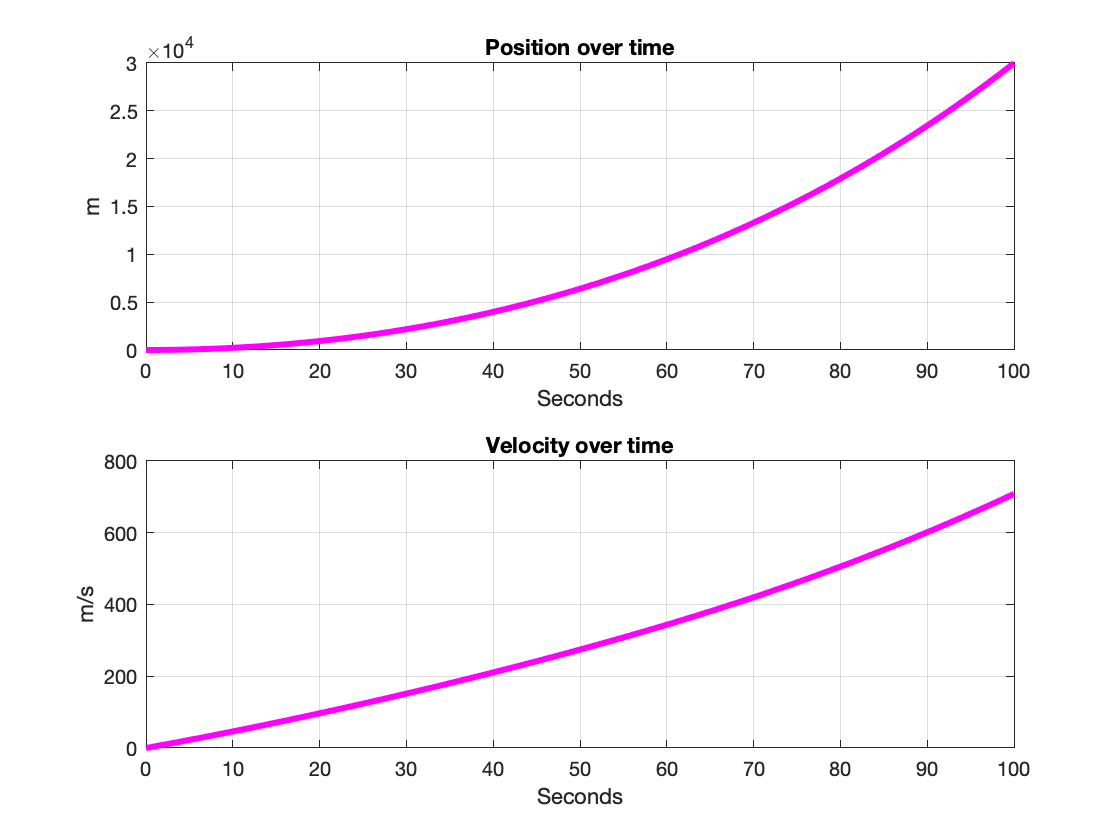

% Plots for the report - Matlab 
clf

% Position
subplot(2,1,1);
plot(t, y(:,3),'m','LineWidth',3);
title("Position over time")
xlabel("Seconds")
ylabel("m")
hold off 
grid on 

% Velocity
subplot(2,1,2);
plot (t, y(:,6),'m','LineWidth',3);

title("Velocity over time")
xlabel("Seconds")
ylabel("m/s")
grid on 
hold off